clear;
clc;
close all;

## % Karplus Strong

function y = karplusStrong(freq, duracao, fs)
% karplusStrong: Gera um som de corda
% dedilhada usando o algoritmo de Karplus-Strong.
% freq: Frequ^encia fundamental da corda em Hz.
% duracao: Dura ̧c~ao do som em segundos.
% fs: Taxa de amostragem em Hz.
% y: Vetor de sa ́ıda do som.
% Tamanho da linha de atraso (arredondado para o inteiro mais pr ́oximo)
N = round(fs / freq);
% N ́umero total de amostras da sa ́ıda
numSamples = round(duracao * fs);
% 1. Excita ̧c~ao: Preencher a linha de atraso com ru ́ıdo branco
% Ru ́ıdo branco uniforme entre -1 e 1
delayLine = (rand(1, N) - 0.5) * 2;
y = zeros(1, numSamples); % Inicializa o vetor de sa ́ıda
% 2. Loop de Karplus-Strong
for n = 1:numSamples
% Obt ́em a amostra mais antiga da linha de atraso
currentSample = delayLine(1);
% Aplica um filtro de m ́edia simples (filtro passa-baixa)
% Isso simula amortecimento e decaimento
% Um filtro comum  ́e a m ́edia simples das duas primeiras amostras
filteredSample = 0.5 * (delayLine(1) + delayLine(2));
% Desloca a linha de atraso
delayLine = [delayLine(2:end), filteredSample];
% Armazena a amostra de sa ́ıda atual
y(n) = currentSample;
end
% Normaliza a sa ́ıda para evitar clipping
y = y / max(abs(y));
end

##  Música Satisfatcion

rng(0);
frequencias = [261.63, 293.66, 329.63, 349.23, 392.00, 440.00, 493.88, 523.25];

dur = 1;            % duração de cada nota (s)
fs = 44100;         % taxa de amostragem (Hz)

bpm = 132;
bps = 132/60;

## Guitarra

freq1 = 440; 

vnotasguita = [-10, -10, -10, -8, -7,...
    -7, -7, -8, -8, -10,...
    -10, -10,30,30, -10, -8, -7 ...
    -7, -7,-8, -8, -10];

vpausasguita = [1, 1.5, 0.5, 0.5, 2, ...
    0.5, 0.5, 0.5, 0.5, 0.5...
    1, 0.5, 0.5, 0.5, 0.5, 0.5, 2, ...
    0.5, 0.5, 0.5, 0.5, 0.5];


musicaguita = [];

for i = 1: 1: length(vpausasguita);
    nota = karplusStrong(freq1*2^(vnotasguita(i)/12),(vpausasguita(i))/bps,fs);
    musicaguita = [musicaguita, nota];
end



## Baixo

freq2 = 220;
% do re fa sol
vnotasbaixo = [75, 75, -17, -15, -14,...
    -12, 75, -12,75, -12, -14, -15,...
    -17, 75,-17,75, -17, -15, -14 ...
    -12, 75, -12, 75, -12, -14, -15];

vpausasbaixo = [2, 0.5, 0.5, 0.5, 0.5, ...
    1, 0.5, 0.5, 0.5, 0.5, 0.5, 0.5...
    1, 0.5, 0.5, 0.5, 0.5, 0.5, 0.5, ...
    1, 0.5, 0.5, 0.5, 0.5, 0.5, 0.5];


musicabaixo = [];

for i = 1: 1: length(vpausasbaixo);
    nota = karplusStrong(freq2*2^(vnotasbaixo(i)/12),(vpausasbaixo(i))/bps,fs);
    musicabaixo = [musicabaixo, nota];
end

musicaguita(end+1)= 0;

sound(musicabaixo + musicaguita,fs)


musicabaixo = highpass(musicabaixo,20,fs);
musicaguita = highpass(musicaguita,20,fs);

## Fourier

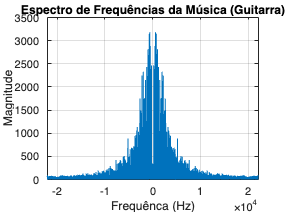


Nguita = length(musicaguita);
tguita = (0:Nguita-1)/fs;
Yguita = fft(musicaguita);
f1 = (-Nguita/2:(Nguita/2)-1)*fs/Nguita;

Y_shifted = fftshift(Yguita);
magnitudeguita = abs(Y_shifted);
figure;
plot (f1, magnitudeguita);
xlabel('Frequênca (Hz)');
ylabel ('Magnitude');
title('Espectro de Frequências da Música (Guitarra)');
grid on

## musicabaixo

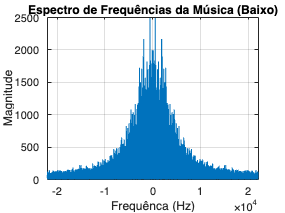

Nbaixo = length(musicabaixo);
tbaixo = (0:Nbaixo-1)/fs;
Ybaixo = fft(musicabaixo);
f2 = (-Nbaixo/2:(Nbaixo/2)-1)*fs/Nbaixo;

baixo_shifted = fftshift(Ybaixo);
magnitudebaixo = abs(baixo_shifted);
figure;
plot (f2, magnitudebaixo);
xlabel('Frequênca (Hz)');
ylabel ('Magnitude');
title('Espectro de Frequências da Música (Baixo)');
grid on

## Energia

%% Frequências de corte
cutfreqguita = 0.95;
cutfreqbaixo = 0.95;

%Energia guitarra
energiaguita = sum((abs(Yguita)).^2);
energiaguita_acum = cumsum((abs(Yguita)).^2);
tamanhoguita = length(energiaguita_acum);

[a,b] = find(energiaguita_acum(1:tamanhoguita/2)>cutfreqguita*energiaguita/2);

%Frequência que corresponde a 95% da energia
FreqG =((b(1)-1)/(tamanhoguita/2))*fs

FreqG = 2.6109e+04



%% Energia Baixo

energiabaixo = sum((abs(Ybaixo)).^2);
energiabaixo_acum = cumsum((abs(Ybaixo)).^2);
tamanhobaixo = length(energiabaixo_acum);

[c,d] = find(energiabaixo_acum(1:tamanhobaixo/2)>cutfreqbaixo*energiabaixo/2);

%Frequência que corresponde a 95% da energia
FreqB = ((d(1)-1)/(tamanhobaixo/2))*fs

FreqB = 3.1842e+04

## Filtros:

## FiltroBaixoPassaBaixa95%


% 
% 
% Nfiltro = 1000;
% 
% omegacorte = (FreqB*2*pi/(2*pi*fs))*pi;
% n = 0 : 1 : 2*Nfiltro;
% hpb = sinc((n-Nfiltro)*omegacorte/pi)*omegacorte/pi;
% hpbw = fftshift(fft(hpb,2*Nfiltro+1));
% 
% janela = blackman(2*Nfiltro+1)';
% hpbj = janela.*hpb;
% Hpbwj= fftshift(fft(hpbj,2*Nfiltro+1));
% ypbjBaixo = conv(hpbj,musicabaixo);
% 
% %sound(ypbjBaixo,fs)



## FiltroGuitarraPassaBaixa95%


% Nfiltro = 1000;
% 
% omegacorte = (FreqG*2*pi/(2*pi*fs))*pi;
% n = 0 : 1 : 2*Nfiltro;
% hpb = sinc((n-Nfiltro)*omegacorte/pi)*omegacorte/pi;
% hpbw = fftshift(fft(hpb,2*Nfiltro+1));
% 
% janela = blackman(2*Nfiltro+1)';
% hpbj = janela.*hpb;
% Hpbwj= fftshift(fft(hpbj,2*Nfiltro+1));
% ypbjGuita = conv(hpbj,musicaguita);
% 
% %sound(ypbjGuita +ypbjBaixo,fs)


## Equalizador

## Passa Baixa:

% Baixo
ganho = 7;
Nfiltro = 1000;

omegacorteb = (300*2*pi/(2*pi*fs))*pi;
n = 0 : 1 : 2*Nfiltro;
hpb = sinc((n-Nfiltro)*omegacorteb/pi)*omegacorteb/pi;
hpbw = fftshift(fft(hpb,2*Nfiltro+1));

janelapb = blackman(2*Nfiltro+1)';
hpbj = janelapb.*hpb;
Hpbwj= fftshift(fft(hpbj,2*Nfiltro+1));
ypbjBaixo = conv(hpbj,musicabaixo);

% Guita

ypbjGuita = conv(hpbj,musicaguita);

sound(ganho*(ypbjGuita +ypbjBaixo),fs)


## Passa Alta

omegacortea = (4000*2*pi/(2*pi*fs))*pi;
n = 0 : 1 : 2*Nfiltro;
hpa = (sinc((n-Nfiltro)*omegacortea/pi)*omegacortea/pi);
hpaw = (fftshift(fft(hpa,2*Nfiltro+1)));

janelapa =  1- blackman(2*Nfiltro+1)';
hpaj = janelapa.*hpa;
Hpawj= fftshift(fft(hpaj,2*Nfiltro+1));
ypajBaixo = conv(hpaj,musicabaixo);

% Guita

ypajGuita = conv(hpaj,musicaguita);

%sound(ganho*(ypajGuita +ypajBaixo),fs)

## Passa Faixa


janelapf = (1- janelapa) - (janelapb)

janelapf = 1.0e-16 *

         0   -0.1388    0.2776   -0.1388   -0.4163    0.5551   -0.2776    0.1388   -0.1388    0.1388         0   -0.2776   -0.4163   -0.2776         0   -0.2776    0.2776   -0.2776   -0.2776    0.2776   -0.2776   -0.5551   -0.1388         0    0.2776   -0.4163    0.2776   -0.4163         0   -0.4163   -0.4163   -0.2776    0.2776    0.4163   -0.4163   -0.2776    0.4163    0.1388         0    0.2776   -0.4163    0.1388    0.4163   -0.4163   -0.4163    0.1388    0.1388    0.1388    0.2776   -0.4163


hpfj = janelapf.*hpa;
Hpfwj= fftshift(fft(hpfj,2*Nfiltro+1));
ypfjBaixo = conv(hpfj,musicabaixo);

ypfjGuita = conv(hpfj,musicaguita);
sound(ganho*(ypfjGuita +ypfjBaixo),fs)


